# Midterm November 16, 2018

## Exercise 1

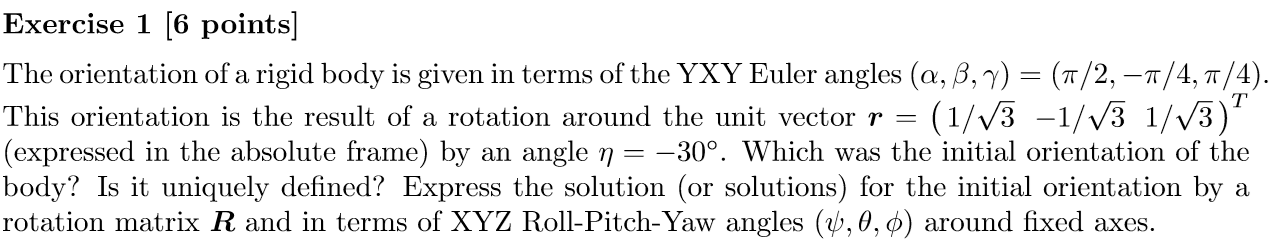

syms alpha beta gamma
[Rx Ry Rz] = getEulerRotationMatrices([gamma, beta,alpha ])

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\gamma \right) & -\sin\left(\gamma \right)\\ 0 & \sin\left(\gamma \right) & \cos\left(\gamma \right) \end{array}\right)$$

$$Ry = \left(\begin{array}{ccc} \cos\left(\beta \right) & 0 & \sin\left(\beta \right)\\ 0 & 1 & 0\\ -\sin\left(\beta \right) & 0 & \cos\left(\beta \right) \end{array}\right)$$

$$Rz = \left(\begin{array}{ccc} \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


% Eugler angle matrices are multipled in forward order. 
% Not reversed, like roll-pitch-yaw angles

RZYX = Rx*Ry*Rz

$$RZYX = \left(\begin{array}{ccc} \cos\left(\alpha \right)\,\cos\left(\beta \right) & -\cos\left(\beta \right)\,\sin\left(\alpha \right) & \sin\left(\beta \right)\\ \cos\left(\gamma \right)\,\sin\left(\alpha \right)+\cos\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\alpha \right)\,\cos\left(\gamma \right)-\sin\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right) & -\cos\left(\beta \right)\,\sin\left(\gamma \right)\\ \sin\left(\alpha \right)\,\sin\left(\gamma \right)-\cos\left(\alpha \right)\,\cos\left(\gamma \right)\,\sin\left(\beta \right) & \cos\left(\alpha \right)\,\sin\left(\gamma \right)+\cos\left(\gamma \right)\,\sin\left(\alpha \right)\,\sin\left(\beta \right) & \cos\left(\beta \right)\,\cos\left(\gamma \right) \end{array}\right)$$

[R_total, R_set] = getRotMatProduct('ZYX',1,[alpha, beta, gamma])

$$R\_total = \left(\begin{array}{ccc} \cos\left(\alpha \right)\,\cos\left(\beta \right) & -\cos\left(\beta \right)\,\sin\left(\alpha \right) & \sin\left(\beta \right)\\ \cos\left(\gamma \right)\,\sin\left(\alpha \right)+\cos\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\alpha \right)\,\cos\left(\gamma \right)-\sin\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right) & -\cos\left(\beta \right)\,\sin\left(\gamma \right)\\ \sin\left(\alpha \right)\,\sin\left(\gamma \right)-\cos\left(\alpha \right)\,\cos\left(\gamma \right)\,\sin\left(\beta \right) & \cos\left(\alpha \right)\,\sin\left(\gamma \right)+\cos\left(\gamma \right)\,\sin\left(\alpha \right)\,\sin\left(\beta \right) & \cos\left(\beta \right)\,\cos\left(\gamma \right) \end{array}\right)$$

R_set = 3×1 cell array
    {3×3 sym}
    {3×3 sym}
    {3×3 sym}


angles = [pi/3, pi/3, -pi/2]

angles =     1.0472    1.0472   -1.5708


% substitute the value of the angles
R_0_f = subs(R_total,[alpha, beta, gamma], angles)

$$R\_0\_f = \left(\begin{array}{ccc} \frac{1}{4} & -\frac{\sqrt{3}}{4} & \frac{\sqrt{3}}{2}\\ -\frac{\sqrt{3}}{4} & \frac{3}{4} & \frac{1}{2}\\ -\frac{\sqrt{3}}{2} & -\frac{1}{2} & 0 \end{array}\right)$$

determinant = simplify(det(R_0_f))

$$determinant = 1$$

 r=sym('r',[3,1])

$$r = \left(\begin{array}{c} r_{1}\\ r_{2}\\ r_{3} \end{array}\right)$$

angle=sym('theta')

$$angle = \theta$$

A_=[sqrt(1/2),0,sqrt(1/2);
    0,-1,0;
    sqrt(1/2),0,-sqrt(1/2)]

A_ =     0.7071         0    0.7071
         0   -1.0000         0
    0.7071         0   -0.7071


A_R_B=simplify(getRotAroundVector(r,angle))

$$A\_R\_B = \begin{array}{l} \left(\begin{array}{ccc} {r_{1}}^{2}-\cos\left(\theta \right)\,\left({r_{1}}^{2}-1\right) & r_{1}\,r_{2}-r_{3}\,\sin\left(\theta \right)-\sigma_{3} & r_{1}\,r_{3}+r_{2}\,\sin\left(\theta \right)-\sigma_{2}\\ r_{1}\,r_{2}+r_{3}\,\sin\left(\theta \right)-\sigma_{3} & {r_{2}}^{2}-\cos\left(\theta \right)\,\left({r_{2}}^{2}-1\right) & r_{2}\,r_{3}-r_{1}\,\sin\left(\theta \right)-\sigma_{1}\\ r_{1}\,r_{3}-r_{2}\,\sin\left(\theta \right)-\sigma_{2} & r_{2}\,r_{3}+r_{1}\,\sin\left(\theta \right)-\sigma_{1} & {r_{3}}^{2}-\cos\left(\theta \right)\,\left({r_{3}}^{2}-1\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r_{2}\,r_{3}\,\cos\left(\theta \right)\\ \sigma_{2}=r_{1}\,r_{3}\,\cos\left(\theta \right)\\ \sigma_{3}=r_{1}\,r_{2}\,\cos\left(\theta \right) \end{array}$$

 R_r_theta_=solve(A_R_B==R_0_f)

R_r_theta_ = struct with fields:
       r1: [2×1 sym]
       r2: [2×1 sym]
       r3: [2×1 sym]
    theta: [2×1 sym]


vpa([ R_r_theta_.r1, R_r_theta_.r2, R_r_theta_.r3, R_r_theta_.theta])

$$ans = \left(\begin{array}{cccc} -0.92387953251128675612818318939679 & 0 & -0.3826834323650897717284599840304 & 3.1415926535897932384626433832795\\ 0.92387953251128675612818318939679 & 0 & 0.3826834323650897717284599840304 & 3.1415926535897932384626433832795 \end{array}\right)$$

 yy=1

yy = 1

% % Calculate the rotation of the body around the unit vector
% % unit_vector = [1/sqrt(3), -1/sqrt(3) 1/sqrt(3)].'
% % eta = deg2rad(-30)

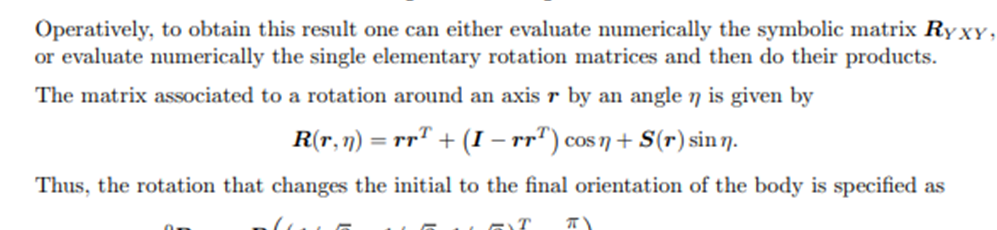.

% r=sym('r',[3,1]);
% angle=sym('theta');
% % A_=[-0.5,-A,0;
% %     0,0,-1;
% %     a,-0.5,0];
% A_R_B=getRotAroundVector(r,angle)

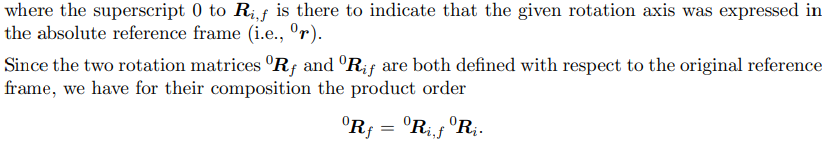

% R_0_i = R_0_if.'*R_0_f; % Initial position expressed in absolute frame
% eval(R_0_i)

Get the Roll_Picth_Yaw matrix equivalent. Inverse problem

% syms psi theta phi
% [R_total_rpy, R_set_rpy] = getRotMatProduct('XYZ',1,[psi theta phi])

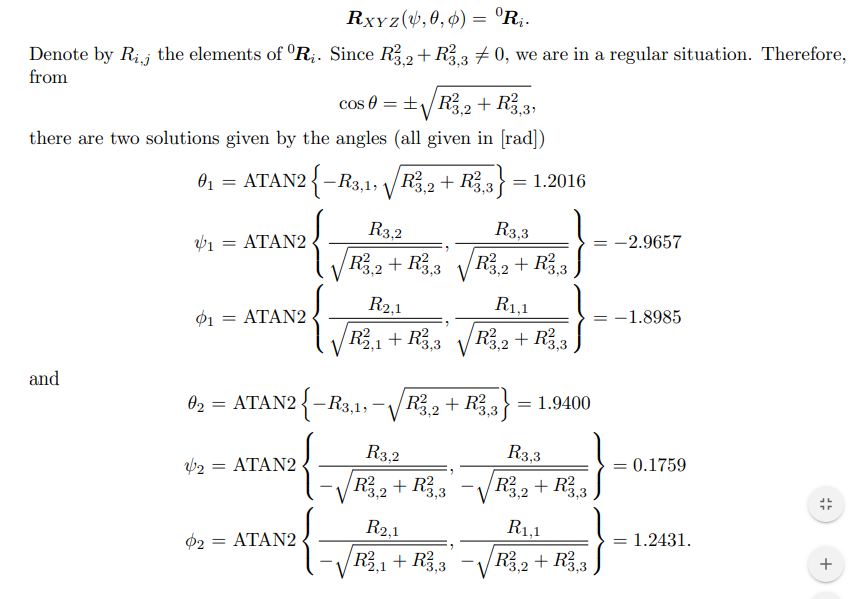

% angs = solve(R_total_rpy == R_0_i)

% % Peter Corke function to get the Roll-Pitch-Yaw angles
% tr2rpy(R_0_i,'zyx') %inverse order in regression

## Exercise 2

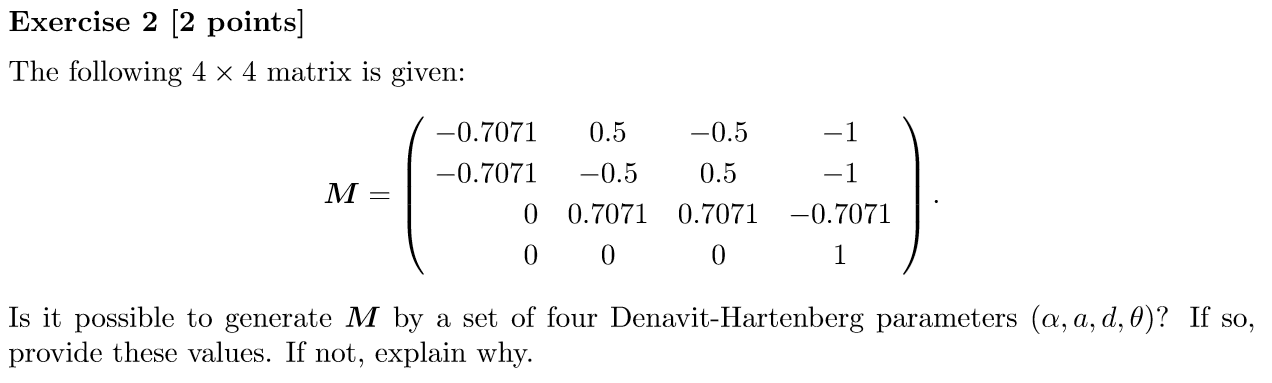

The last row is composed by three zeros and a 1, which are the correct usual values. The vector in the fourth column can have any value, since it's a possition. The upper left 3x3 matrix must be a rotational matrix, that is, orthonormal matrix: The determinant must be one, it's transpose is the same inverse.

Check orthonormality of the rotation martrix.

% M = [-0.7071 0.5 -0.5 -1;
%      -0.7071 -0.5 0.5 -1;
%       0 0.7071 0.7071 -0.7071;
%       0 0 0 1]
%   Mpi1=(1/pi)*M
% R = M(1:3,1:3)
%  

Es necesario comprobar que M es homgeno y ortogonal el determinante debe ser +1

% round(inv(R),4)==round(R.',4) % since all of them are ones, it meets the req.
% det(R)
% det(inv(R))

% syms alpha a d theta m07 m05;
% Mtd=[-m07 m05 -m05 -1;-m07 -m05 m05 -1;0 m07 m07 -m07;0 0 0 1]
% DHParams = [alpha a d theta]
% 
% DHMatrix = getDHSymMatrix() % Generic rotation translation matrix
% 
% DHMatrix == Mtd
% rd=solve(DHMatrix == Mtd)
% %[alpha_m a_m d_m theta_m ] = solve(DHMatrix == Mtd, DHParams)
% M2 = subs(DHMatrix, DHParams, [pi/4,sqrt(2), -sqrt(2)/2,-3*pi/4])
% eval(M2)
% 
% %Cannot find the answer by 'solve' because the values are not exact.
% 
% dh = [-pi/2 220 346 0;
%        pi/2  0  140 0]
% TB0 = getTransformationMatrix(dh, 'alpha')

% Rsym = DHMatrix(1:3,1:3)
% tr2rpy(R)

## Exercise 3

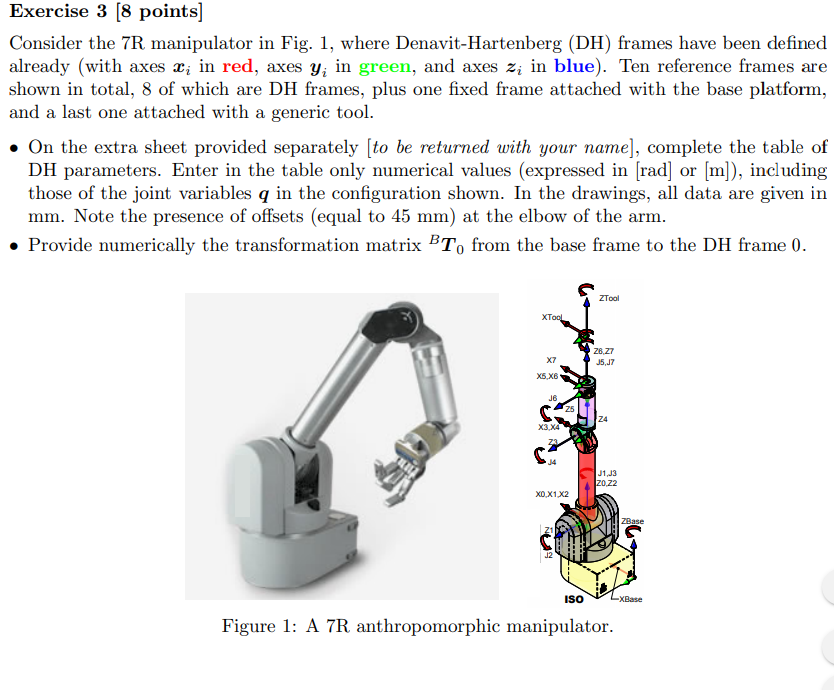

% clear all, close all, clc
% a3=45/1000
% a4=-a3
% d3=550/1000
% d5=300/1000
% d7=60/1000
% % De Luca's approach
% links = [
%     Revolute('alpha', -pi/2, 'a', 0 ,'d', 0);
%     Revolute('alpha',  pi/2, 'a', 0 ,'d', 0);
%     Revolute('alpha', -pi/2, 'a', a3 ,'d', d3);
%     Revolute('alpha',  pi/2, 'a', a4 ,'d',0);
%     Revolute('alpha', -pi/2, 'a', 0 ,'d', d5);
%     Revolute('alpha',  pi/2, 'a', a3 ,'d', 0);
%     Revolute('alpha',    0 , 'a', 0 ,'d', d7);
% 
% 
% 
% 
% %     Revolute('a', len1, 'alpha', 0 ,'d', 0);
%     ];
% c600 = SerialLink(links);
% c600.teach([0 0 0 0 0 0 0],'view','x')
% 

## Exercise 5

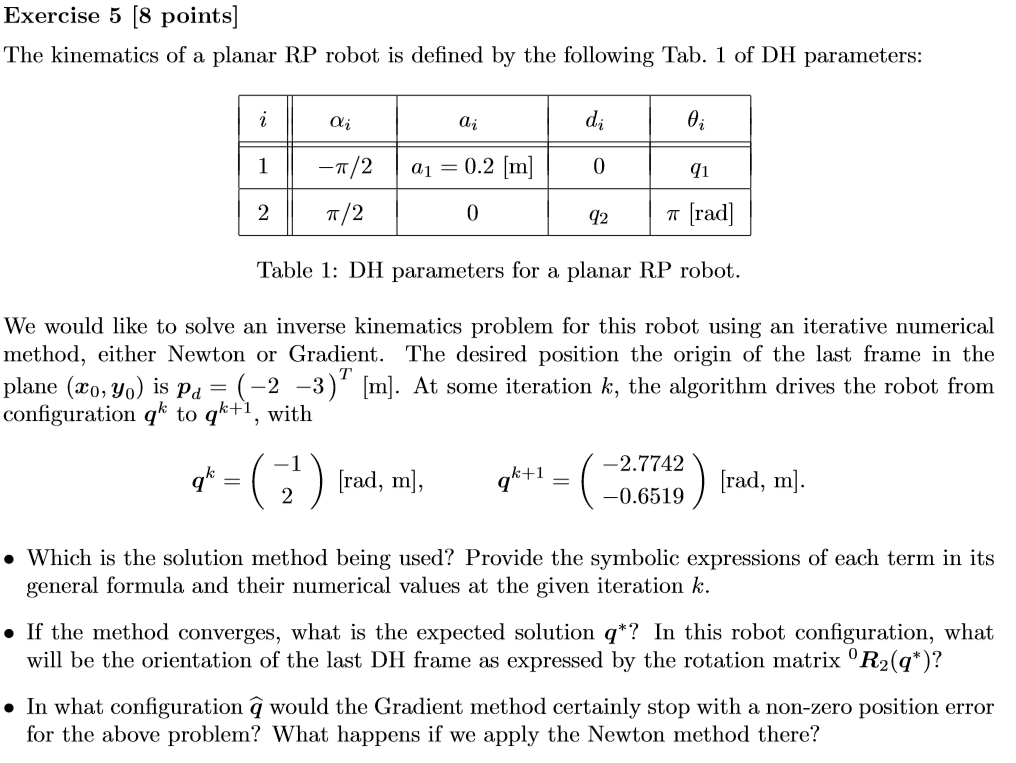

% syms a1 q1 q2 
% dhTable = [-pi/2, a1, 0, q1;
%             pi/2, 0, q2, pi]
% 
% [T_total T_Partial] = getTransformationMatrix(dhTable, 'alpha')

% p = T_total(1:2,4) % Planar position of the EE
% J = jacobian(p,[q1 q2])

% L(1)=Link('alpha', -pi/2, 'a', 0.2, 'd', 0);
% L(2)=Link('alpha', -pi/2, 'a', 0, 'theta', pi, 'qlim', [0,10]);
% robot1 = SerialLink(L,'name','RPRobot')
% robot1.teach

% pd = [-2, -3, 0].'
% q = fminsearch( @(q) norm( robot1.fkine(q).t - pd ), [0 0] )
% %robot1.ikine(pd)

% robot1.fkine([0,0]).t

clear all, close all, clc
syms A B C D q1 q2
Njoints=6;
q=sym('q',[Njoints,1]);
L_=3

L_ = 3

d1_=1;
d2_=1;
syms alpha beta gamma L

a1=A

$$a1 = A$$

a2=6

a2 = 6

dhTable=[pi/2,0,128,q(1);
         0,612.7,0,q(2);
         0,571.6,0,q(3);
         pi/2,0,163.9,q(4);
         -pi/2,0,-115.7,q(5);
         0,0,92.2,q(6)
         ];
links = [
    Revolute('alpha', pi/2,'a', 0,'d', 128)
%     Prismatic('qlim', [0 5],'alpha',-pi/2,'theta',0);
    Revolute('alpha', 0,      'a', 612.7,'d', 0);
    Revolute('alpha', 0,      'a', 571.6,'d', 0);
    Revolute('alpha',  pi/2,   'a', 0,'d', 163.9);
    Revolute('alpha', -pi/2,   'a', 0,'d', -115.7);
     Revolute('alpha',  0,      'a', 0,'d', 92.2);

    ];
c600 = SerialLink(links);
c600.teach([0,pi/2,0,-pi/2,0,0],'view','y')%,0,-pi/2,0,0
[T_total T_Partial,RTotal,RPartial,PTotal, PPartial] = getTransformationMatrix(dhTable, 'alpha')

T_Partial = 1×6 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}


$$RTotal = \begin{array}{l} \left(\begin{array}{ccc} \cos\left(q_{6}\right)\,\sigma_{3}-\sigma_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{6}\right) & -\sin\left(q_{6}\right)\,\sigma_{3}-\sigma_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{6}\right) & \cos\left(q_{5}\right)\,\sin\left(q_{1}\right)-\sigma_{4}\,\cos\left(q_{1}\right)\,\sin\left(q_{5}\right)\\ -\cos\left(q_{6}\right)\,\sigma_{2}-\sigma_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{6}\right) & \sin\left(q_{6}\right)\,\sigma_{2}-\sigma_{1}\,\cos\left(q_{6}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\cos\left(q_{5}\right)-\sigma_{4}\,\sin\left(q_{1}\right)\,\sin\left(q_{5}\right)\\ \sigma_{4}\,\sin\left(q_{6}\right)+\sigma_{1}\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right) & \sigma_{4}\,\cos\left(q_{6}\right)-\sigma_{1}\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right) & -\sigma_{1}\,\sin\left(q_{5}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\sin\left(q_{5}\right)-\sigma_{4}\,\cos\left(q_{5}\right)\,\sin\left(q_{1}\right)\\ \sigma_{3}=\sin\left(q_{1}\right)\,\sin\left(q_{5}\right)+\sigma_{4}\,\cos\left(q_{1}\right)\,\cos\left(q_{5}\right)\\ \sigma_{4}=\cos\left(q_{2}+q_{3}+q_{4}\right) \end{array}$$

RPartial = 1×6 cell array
    {3×3 sym}    {3×3 sym}    {3×3 sym}    {3×3 sym}    {3×3 sym}    {3×3 sym}


$$PTotal = \begin{array}{l} \left(\begin{array}{c} \frac{1639\,\sin\left(q_{1}\right)}{10}+\frac{6127\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)}{10}+\frac{461\,\cos\left(q_{5}\right)\,\sin\left(q_{1}\right)}{5}-\frac{461\,\sigma_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{5}\right)}{5}-\frac{1157\,\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\sin\left(q_{4}\right)}{10}-\frac{1157\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\cos\left(q_{4}\right)}{10}+\frac{2858\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)}{5}-\frac{2858\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{5}\\ \frac{6127\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}{10}-\frac{461\,\cos\left(q_{1}\right)\,\cos\left(q_{5}\right)}{5}-\frac{1639\,\cos\left(q_{1}\right)}{10}-\frac{2858\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{5}-\frac{461\,\sigma_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{5}\right)}{5}-\frac{1157\,\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{4}\right)}{10}-\frac{1157\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{1}\right)}{10}+\frac{2858\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)}{5}\\ \frac{2858\,\sin\left(q_{2}+q_{3}\right)}{5}+\frac{6127\,\sin\left(q_{2}\right)}{10}-\sin\left(q_{5}\right)\,\left(\frac{461\,\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{4}\right)}{5}+\frac{461\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{4}\right)}{5}\right)+\frac{1157\,\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{4}\right)}{10}-\frac{1157\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{4}\right)}{10}+128 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}+q_{3}+q_{4}\right) \end{array}$$

PPartial = 1×6 cell array
    {3×1 sym}    {3×1 sym}    {3×1 sym}    {3×1 sym}    {3×1 sym}    {3×1 sym}


sincos =getShortNotation_SinCos(6)

sincos = 6×2 cell array
    { 6×1 sym}    { 6×1 sym}
    {21×1 sym}    {21×1 sym}
    {56×1 sym}    {56×1 sym}
    { 6×1 sym}    { 6×1 sym}
    {21×1 sym}    {21×1 sym}
    {56×1 sym}    {56×1 sym}


digits(4)
toShortNotation(vpa(T_total),sincos)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} c_{6}\,\sigma_{2}-1.0\,c_{1}\,s_{6}\,s_{2,3,4} & -1.0\,s_{6}\,\sigma_{2}-1.0\,c_{1}\,c_{6}\,s_{2,3,4} & c_{5}\,s_{1}-1.0\,c_{1}\,c_{2,3,4}\,s_{5} & 163.9\,s_{1}+612.7\,c_{1}\,c_{2}+92.2\,c_{5}\,s_{1}+571.6\,c_{1}\,c_{2}\,c_{3}-115.7\,c_{1}\,c_{4}\,s_{2,3}-115.7\,c_{1}\,c_{2,3}\,s_{4}-92.2\,c_{1}\,c_{2,3,4}\,s_{5}-571.6\,c_{1}\,s_{2}\,s_{3}\\ -1.0\,c_{6}\,\sigma_{1}-1.0\,s_{1}\,s_{6}\,s_{2,3,4} & s_{6}\,\sigma_{1}-1.0\,c_{6}\,s_{1}\,s_{2,3,4} & -1.0\,c_{1}\,c_{5}-1.0\,c_{2,3,4}\,s_{1}\,s_{5} & 612.7\,c_{2}\,s_{1}-92.2\,c_{1}\,c_{5}-163.9\,c_{1}+571.6\,c_{2}\,c_{3}\,s_{1}-115.7\,c_{4}\,s_{1}\,s_{2,3}-115.7\,c_{2,3}\,s_{1}\,s_{4}-92.2\,c_{2,3,4}\,s_{1}\,s_{5}-571.6\,s_{1}\,s_{2}\,s_{3}\\ c_{2,3,4}\,s_{6}+c_{5}\,c_{6}\,s_{2,3,4} & c_{6}\,c_{2,3,4}-1.0\,c_{5}\,s_{6}\,s_{2,3,4} & -1.0\,s_{5}\,s_{2,3,4} & 612.7\,s_{2}+571.6\,s_{2,3}+115.7\,c_{4}\,c_{2,3}-115.7\,s_{4}\,s_{2,3}-1.0\,s_{5}\,\left(92.2\,c_{4}\,s_{2,3}+92.2\,c_{2,3}\,s_{4}\right)+128.0\\ 0 & 0 & 0 & 1.0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=c_{1}\,s_{5}-1.0\,c_{5}\,c_{2,3,4}\,s_{1}\\ \sigma_{2}=s_{1}\,s_{5}+c_{1}\,c_{5}\,c_{2,3,4} \end{array}$$

sincos =getShortNotation_SinCos(6)

sincos = 6×2 cell array
    { 6×1 sym}    { 6×1 sym}
    {21×1 sym}    {21×1 sym}
    {56×1 sym}    {56×1 sym}
    { 6×1 sym}    { 6×1 sym}
    {21×1 sym}    {21×1 sym}
    {56×1 sym}    {56×1 sym}


digits(4)
toShortNotation(vpa(PTotal),sincos)

$$ans = \left(\begin{array}{c} 163.9\,s_{1}+612.7\,c_{1}\,c_{2}+92.2\,c_{5}\,s_{1}+571.6\,c_{1}\,c_{2}\,c_{3}-115.7\,c_{1}\,c_{4}\,s_{2,3}-115.7\,c_{1}\,c_{2,3}\,s_{4}-92.2\,c_{1}\,c_{2,3,4}\,s_{5}-571.6\,c_{1}\,s_{2}\,s_{3}\\ 612.7\,c_{2}\,s_{1}-92.2\,c_{1}\,c_{5}-163.9\,c_{1}+571.6\,c_{2}\,c_{3}\,s_{1}-115.7\,c_{4}\,s_{1}\,s_{2,3}-115.7\,c_{2,3}\,s_{1}\,s_{4}-92.2\,c_{2,3,4}\,s_{1}\,s_{5}-571.6\,s_{1}\,s_{2}\,s_{3}\\ 612.7\,s_{2}+571.6\,s_{2,3}+115.7\,c_{4}\,c_{2,3}-115.7\,s_{4}\,s_{2,3}-1.0\,s_{5}\,\left(92.2\,c_{4}\,s_{2,3}+92.2\,c_{2,3}\,s_{4}\right)+128.0 \end{array}\right)$$

q_=[0,pi/2,0,-pi/2,0,0]'

q_ =          0
    1.5708
         0
   -1.5708
         0
         0



vpa(subs(PTotal,q,q_))

$$ans = \left(\begin{array}{c} 0\\ -256.1\\ 1428.0 \end{array}\right)$$